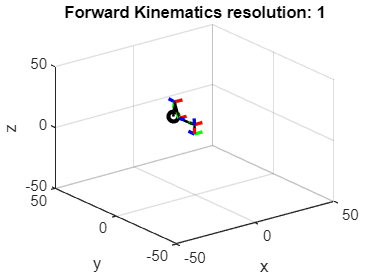

clear all
pos = [0,-17.5,6.3];
phi = -85;
[result1,result2,result3,result4] = IK(pos(1),pos(2),pos(3),phi);

res1 = FK_plot(result1(1),result1(2),result1(3),result1(4),1);

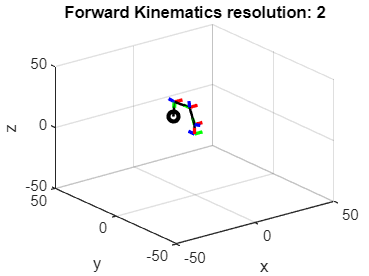

res2 = FK_plot(result2(1),result2(2),result2(3),result2(4),2);

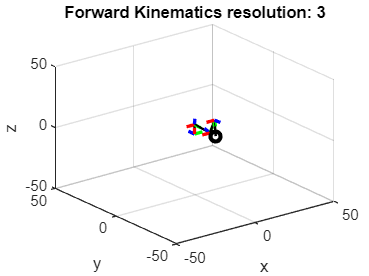

res3 = FK_plot(result3(1),result3(2),result3(3),result3(4),3);

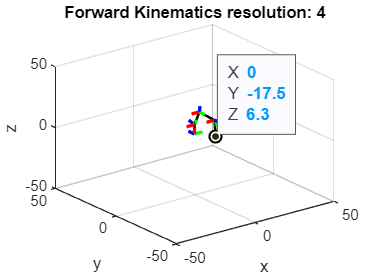

res4 = FK_plot(result4(1),result4(2),result4(3),result4(4),4);

function [result1,result2,result3,result4] = IK(pos_x,pos_y,pos_z,phi)
            target_end_pos = [pos_x,pos_y,pos_z];
            a2 = 13;
            a3 = 12.4;
            a4 = 12.6;
            beta = atand(0.024/0.128);
            r3 = sqrt(pos_x^2 + pos_y^2);
            z3 = pos_z - 7.7;
            % randomly chose a sum for all angles: 49.4 - 34.38 - 60 (temp val)
            r2 = r3 - a4*cosd(phi);
            z2 = z3 - a4*sind(phi); 
            cos_theta3 = (r2^2+z2^2-a2^2-a3^2) / (2*a2*a3);
            % no solution case
            if cos_theta3 < -1 || cos_theta3 > 1
                msgbox('No solution exists')
            end
            theta3_temp = acosd(cos_theta3);
            theta3_temp_ = -acosd(cos_theta3);
            theta3 = theta3_temp - beta + 90;
            theta3_ = theta3_temp_ - beta + 90;
            k1 = a2 + a3 * cosd(theta3_temp) ;
            k2 = a3 * sind(theta3_temp);
            k2_ = a3 * sind(theta3_temp_);
            theta2_temp = atand(z2/r2) - atand(k2/k1);
            theta2_temp_ = atand(z2/r2) - atand(k2_/k1);
            theta2 = 90 - theta2_temp - beta;
            theta2_ = 90 - theta2_temp_ - beta;
            theta4 = phi - theta2_temp - theta3_temp;
            theta4_ = phi - theta2_temp_ - theta3_temp_;
            theta1 = atand(pos_y/pos_x);
            theta1_ = -atand(pos_y/pos_x);
            if theta1 == 0
                theta1 = 0;
                theta1_ = 180;
            end
            res1 = [theta1, theta2, theta3, theta4];
            res2 = [theta1, theta2_, theta3_, theta4_];
            res3 = [theta1_, theta2, theta3, theta4];
            res4 = [theta1_, theta2_, theta3_, theta4_];
            % verfity end_pos
            T_mat1 = DHTransform(theta1, theta2, theta3, theta4, beta);
            T_mat2 = DHTransform(theta1, theta2_, theta3_, theta4_, beta);
            T_mat3 = DHTransform(theta1_, theta2, theta3, theta4, beta);
            T_mat4 = DHTransform(theta1_, theta2_, theta3_, theta4_, beta);
            T_end_pos1 = T_mat1(1:3, 4);
            T_end_pos2 = T_mat2(1:3, 4);
            T_end_pos3 = T_mat3(1:3, 4);
            T_end_pos4 = T_mat4(1:3, 4);
            diff1 = T_end_pos1 - target_end_pos;
            diff2 = T_end_pos2 - target_end_pos;
            diff3 = T_end_pos3 - target_end_pos;
            diff4 = T_end_pos4 - target_end_pos;
            result1 = res1;
            result2 = res2;
            result3 = res3;
            result4 = res4;
            % if all(abs(diff1) < 0.1)
            %     result = res1;
            % end
            % if all(abs(diff2)< 0.1) 
            %     result = res2;
            % end
            % if all(abs(diff3)< 0.1) 
            %     result = res3;
            % end
            % if all(abs(diff4)< 0.1) 
            %     result = res4;
            % end
end

function final_mat = threeDTransform(alpha, a, d, theta)
final_mat = [cosd(theta),             -sind(theta),            0,            a;
             sind(theta)*cosd(alpha), cosd(theta)*cosd(alpha), -sind(alpha), -sind(alpha)*d;
             sind(theta)*sind(alpha), cosd(theta)*sind(alpha), cosd(alpha),  cosd(alpha)*d;
             0,                       0,                       0,            1];
end

function T_final = DHTransform(theta1, theta2, theta3, theta4, beta)
T0 = eye(4);
T1 = T0 * threeDTransform(0, 0, 7.7, theta1);
T2 = T1 * threeDTransform(-90, 0, 0, -90);
T3 = T2 * threeDTransform(0, 0, 0, -beta-theta2);
T3 = T3 * threeDTransform(0, 13, 0, 0);
T4 = T3 * threeDTransform(0, 0, 0, beta-90);
T5 = T4 * threeDTransform(0, 0, 0, theta3); 
T5 = T5 * threeDTransform(0, 12.4, 0, 0);
T6 = T5 * threeDTransform(0, 0, 0, theta4);
T6 = T6 * threeDTransform(0, 12.6, 0, 0);
T_final = T6;
end

function res = FK_plot(theta1,theta2,theta3,theta4,res)
beta = atand(0.024/0.128);
T0 = eye(4);
min_lim = -50;
max_lim = 50;

T1 = T0 * threeDTransform(0, 0, 7.7, theta1) ;
x_dir1 = T1(1:3, 1)*5;
y_dir1 = T1(1:3, 2)*5;
z_dir1 = T1(1:3, 3)*5;
center1 = T1(:, 4);

% frame change (i=2)
T2 = T1 * threeDTransform(-90, 0, 0, -90) ;
T2 = T2 * threeDTransform(0, 0, 0, -beta-theta2);
x_dir2 = T2(1:3, 1)*5;
y_dir2 = T2(1:3, 2)*5;
z_dir2 = T2(1:3, 3)*5;
center2 = T2(:, 4);

% second transformation (i=3)
T3 = T2 * threeDTransform(0, 13, 0, 0);
x_dir3 = T3(1:3, 1)*5;
y_dir3 = T3(1:3, 2)*5;
z_dir3 = T3(1:3, 3)*5;
center3 = T3(:, 4);

% frame change (i=4)
T4 = T3 * threeDTransform(0, 0, 0, beta-90) ;
x_dir4 = T4(1:3, 1)*5;
y_dir4 = T4(1:3, 2)*5;
z_dir4 = T4(1:3, 3)*5;
center4 = T4(:, 4);

% third transformation (i=5)
T5 = T4 * threeDTransform(0, 0, 0, theta3) ;
T5 = T5 * threeDTransform(0, 12.4, 0, 0);
x_dir5 = T5(1:3, 1)*5;
y_dir5 = T5(1:3, 2)*5;
z_dir5 = T5(1:3, 3)*5;
center5 = T5(:, 4);

% fourth transformation (i=6)
T6 = T5 * threeDTransform(0, 0, 0, theta4) ;
T6 = T6 * threeDTransform(0, 12.6, 0, 0) ;
x_dir6= T6(1:3, 1)*5;
y_dir6 = T6(1:3, 2)*5;
z_dir6 = T6(1:3, 3)*5;
center6 = T6(:, 4);

min_lim = -50;
max_lim = 50;

% base frame (i=0)
plot3([0 5], [0 0], [0 0], 'LineWidth', 2, 'Color', 'g');
hold on
plot3([0 0], [0 5], [0 0], 'LineWidth', 2, 'Color', 'b');
hold on
plot3([0 0], [0 0], [0 5], 'LineWidth', 2, 'Color', 'r');
hold on

line0 = plot3([0 center1(1)], [0, center1(2)], [0, center1(3)], 'LineWidth', 1.5, 'Color', 'black');

% change frame! (i=2)
frame0_1 = plot3([center2(1) center2(1)+x_dir2(1)], [center2(2) center2(2)+x_dir2(2)], [center2(3) center2(3)+x_dir2(3)], 'LineWidth', 2, 'Color', 'g');
hold on
frame0_2 = plot3([center2(1) center2(1)+ y_dir2(1)], [center2(2) center2(2)+y_dir2(2)], [center2(3) center2(3)+y_dir2(3)], 'LineWidth', 2, 'Color', 'b');
hold on
frame0_3 = plot3([center2(1) center2(1)+ z_dir2(1)], [center2(2) center2(2)+z_dir2(2)], [center2(3) center2(3)+z_dir2(3)], 'LineWidth', 2, 'Color', 'r');
hold on

line1 = plot3([center2(1) center3(1)], [center2(2) center3(2)], [center2(3) center3(3)], 'LineWidth', 1.5, 'Color', 'black');


% change frame! (i=4)
frame1_1 = plot3([center4(1) center4(1)+x_dir5(1)], [center4(2) center4(2)+x_dir5(2)], [center4(3) center4(3)+x_dir5(3)], 'LineWidth', 2, 'Color', 'g');
hold on
frame1_2 = plot3([center4(1) center4(1)+ y_dir5(1)], [center4(2) center4(2)+y_dir5(2)], [center4(3) center4(3)+y_dir5(3)], 'LineWidth', 2, 'Color', 'b');
hold on
frame1_3 = plot3([center4(1) center4(1)+ z_dir5(1)], [center4(2) center4(2)+z_dir5(2)], [center4(3) center4(3)+z_dir5(3)], 'LineWidth', 2, 'Color', 'r');
hold on

line2 = plot3([center4(1) center5(1)], [center4(2) center5(2)], [center4(3) center5(3)], 'LineWidth', 1.5, 'Color', 'black');

% third transformation (i=5)
frame2_1 = plot3([center5(1) center5(1)+x_dir6(1)], [center5(2) center5(2)+x_dir6(2)], [center5(3) center5(3)+x_dir6(3)], 'LineWidth', 2.5, 'Color', 'g');
hold on
frame2_2 = plot3([center5(1) center5(1)+y_dir6(1)], [center5(2) center5(2)+y_dir6(2)], [center5(3) center5(3)+y_dir6(3)], 'LineWidth', 2, 'Color', 'b');
hold on
frame2_3 = plot3([center5(1) center5(1)+z_dir6(1)], [center5(2) center5(2)+z_dir6(2)], [center5(3) center5(3)+z_dir6(3)], 'LineWidth', 2, 'Color', 'r');
hold on

line3 = plot3([center5(1) center6(1)], [center5(2) center6(2)], [center5(3) center6(3)], 'LineWidth', 1.5, 'Color', 'black');

% fourth transformation (i=6)
hold on
line4 = scatter3(center6(1), center6(2), center6(3), 'o', 'LineWidth', 2.5,'MarkerEdgeColor','k');

xlim([min_lim max_lim]);
ylim([min_lim max_lim]);
zlim([min_lim max_lim]);
xlabel('x');
ylabel('y');
zlabel('z');
grid on
title(['Forward Kinematics resolution: ',num2str(res)]);
hold off
end